# European Gasoline Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

gasprices = readtable("../data/gasprices.csv", "Range", "A5:K24");

Year = gasprices.Year;
France = gasprices.France;
Germany = gasprices.Germany;
Italy = gasprices.Italy;

Fr2 = France(2);
France(1) = Fr2; % replace a missing value
Italy

Italy =     4.5900
    4.5000
    4.5300
    3.6800
    3.7000
    4.0000
    4.3900
    4.0700
    3.8400
    3.8700


## Task 1

The fourth element is the first element that isn't `NaN`.  You will approximate the first three elements with the fourth one. 

It4 = Italy(4)

It4 = 3.6800

## Task 2

You can assign multiple elements of a vector to the same value simultaneously by indexing with a second vector.

For instance, the following code uses an indexing vector to change the second and fourth elements of `v` to `0`.

`v` `=` `[``1` `2` `3` `4` `5``]``;`

`v``([``2` `4``])` `=` `0`

    `[``1` `0` `3` `0` `5``]`

Italy(1:3) = It4

Italy =     3.6800
    3.6800
    3.6800
    3.6800
    3.7000
    4.0000
    4.3900
    4.0700
    3.8400
    3.8700


## Task 3

You can see that the gas prices for 1990-1992 have been updated in the plot at the bottom of the script.  You still need to update the gas prices from 2002-2005.

The prices in USD per gallon during these years were 3.74, 4.53, 5.29, 5.74.

missingPrices = [3.74 4.53 5.29 5.74]

missingPrices =     3.7400    4.5300    5.2900    5.7400


## Task 4

To change multiple values in a vector at once, you can access the elements you want to change and assign a new vector to them.

`v` `=` `[``1` `2` `3` `4` `5``]``;`

`v``([``2` `4``])` `=` `[``10` `20``]`

    `[``1` `10` `3` `20` `5``]`

Italy(13:16) = missingPrices

Italy =     3.6800
    3.6800
    3.6800
    3.6800
    3.7000
    4.0000
    4.3900
    4.0700
    3.8400
    3.8700


This code plots the data.

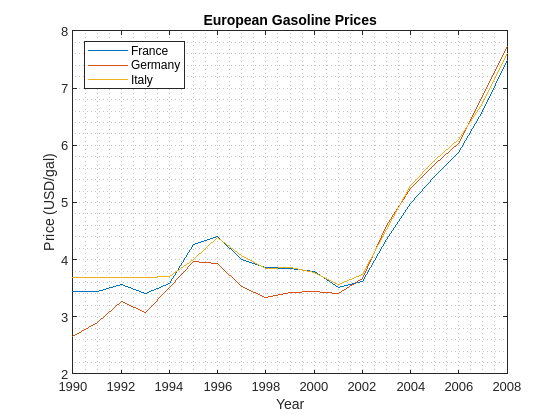

plot(Year,France)
hold on
grid minor
plot(Year,Germany)
plot(Year,Italy)
hold off
title("European Gasoline Prices")
xlabel("Year")
ylabel("Price (USD/gal)")
legend("France"," Germany", "Italy", "Location", "northwest")

## Task 5

You can see in the plot at the end of the script now contains complete, although approximated, data for the Italian gas prices. If you want to remove elements from a vector, you can do so by assigning

`v` `=` `[``1` `2` `3` `4` `5``]``;`

`v``([``2` `4``])` `=` `[]`

    `[``1` `3` `5``]`

Italy(1:3) = [];